# Single Damped Pendulum Project

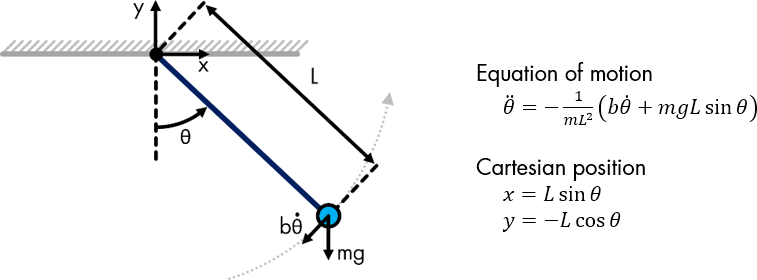

### Pendulum Dynamics

% Define physical parameters
L = 1; % Pendulum length (m)
m = 1; % Pendulum mass (kg)
theta0 = 50; % Initial angle (deg)
b = 1; % Damping (N*m*s/rad)
g = 9.81; % Gravity (m/s^2)

 

% Convert initial angle to radians
theta0 = deg2rad(theta0);

% Numerically solve the pendulum's equation of motion
[t,theta] = pendulumSolver(L,m,b,g,theta0);

% Get the number of elements
N = length(theta);

% Convert to Cartesian coordinates
x = L*sin(theta);
y = -L*cos(theta);

### Pendulum Animation

% Create a new figure for the animation
figure

% Loop through each time step
for k = 1:N
    % Define pendulum string coordinates at time k
    xString = [0, x(k)];   % from origin to mass x-position
    yString = [0, y(k)];   % from origin to mass y-position
    
    % Plot the string
    plot(xString, yString, 'k-', 'LineWidth', 2)
    hold on

    % Direction check and color-coded mass
    if k < N
        if x(k+1) > x(k)
            color = 'r';  % moving right
        else
            color = 'b';  % moving left
        end

        plot(x(k), y(k), 'o', ...
            'MarkerSize', 12, ...
            'MarkerEdgeColor', color, ...
            'MarkerFaceColor', color, ...
            'LineWidth', 1.5)
    end
    hold off
    
    % Optional: formatting
    axis equal
    axis([-L L -L L])  % Adjust as needed
    title(sprintf('Time: %.2f s', t(k)))
    
    xlim([-2.5 2.5])
    ylim([-2.5 1.5])
    drawnow
end

*Copyright 2021 The MathWorks, Inc.*